今回，非線形項や周波数依存減衰を取り入れた媒質でシミュレーションを行った．

文献値はFOUNDATION OF BIOMEDICAL ULTRASOUNDS pp.78から参照した．

TOFマップは閾値法によって得ている．閾値は，全体が筋肉組織であるとした媒質において，トランスデューサ中央部の素子と対向する素子に着目して，波形先頭到達時間と素子間距離から算出した音速値が設定した筋肉組織の音速値と等しくなるように設定した．

今回，その設定が非線形効果を取り入れた今回の媒質での結果についても良好に機能するような設定であるのかを確認する．TOFマップで非連続な値を出す箇所があるのかを確認する．

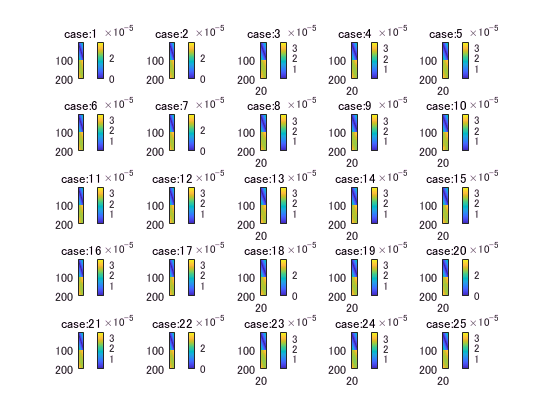

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_16_analyzeRealisticModel')
load('2018_08_16_aveSOS&steSOS_1-25')
figure;
for i = 1:25
    subplot(5,5,i);
    imagesc(tof_cell(:,:,i));
    colorbar
    myfilename = sprintf('case:%d',i);
    title(myfilename);
end

特に非連続な箇所は確認されなかった．正常に機能していると言える．

１．平均音速値をプロットする．非線形なし，ありで比較する．

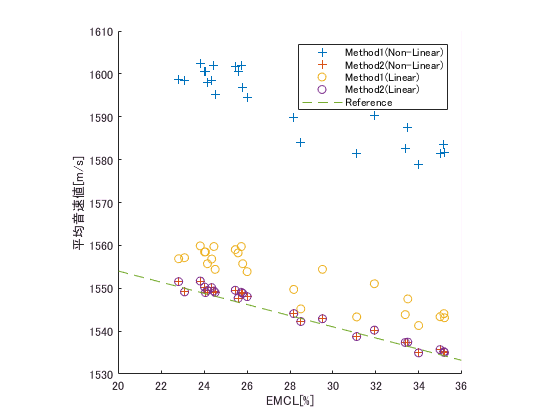

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_16_analyzeRealisticModel')
load('2018_08_16_aveSOS&steSOS_1-25')
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('rate_EMCLs')
[~, num_pattern] = size(aveSOS);
v_muscle = 1580;
v_fat = 1450;
x1 = 20:36;
figure;
hold on
scatter(rate_EMCLs(1,:), aveSOS(1,:),'+');
scatter(rate_EMCLs(1,:), aveSOS2(1,:),'+');
cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\2018_08_12_analyzeRealisticModel')
load('2018_08_12_aveSOS&steSOS_1-25')
load('rate_EMCLs')
scatter(rate_EMCLs(1,:), aveSOS(1,:));
scatter(rate_EMCLs(1,:), aveSOS2(1,:));
plot(x1,v_muscle*(1-x1/100)+v_fat*x1/100,'--');
xlabel('EMCL[%]');
ylabel('平均音速値[m/s]')
legend('Method1(Non-Linear)','Method2(Non-Linear)','Method1(Linear)','Method2(Linear)','Reference')
axis square
hold off

明らかにmethod1(non-linear)の値がlinearと比べて乖離している．

どこか初歩的なミスをしているはず．